## Instantiate Left Right CAD Arms


LeftTable = readtable('resources/icubarm_left_urdf_dhparams.csv');
LeftTable.Properties.VariableNames = {'a', 'd', 'alpha', 'offset', 'min', 'max'};
LeftArm = Revolute('d', LeftTable.d(1), 'a', LeftTable.a(1), 'alpha', deg2rad(LeftTable.alpha(1)), 'offset', deg2rad(LeftTable.offset(1)));
for i=2:height(LeftTable)
   LeftArm = LeftArm + Revolute('d', LeftTable.d(i), 'a', LeftTable.a(i), 'alpha', deg2rad(LeftTable.alpha(i)), 'offset', deg2rad(LeftTable.offset(i)));
end
LeftArm.name = 'Left';

homtable = readtable('resources/icubarm_left_urdf_h0_hn.txt');
h = zeros(4,4);
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{1, k};
        k = k+1;
    end
end
LeftArm.base = h;
                
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{2, k};
        k = k+1;
    end
end
LeftArm.tool = h;


RightTable = readtable('resources/icubarm_right_urdf_dhparams.csv');
RightTable.Properties.VariableNames = {'a', 'd', 'alpha', 'offset', 'min', 'max'};
RightArm = Revolute('d', RightTable.d(1), 'a', RightTable.a(1), 'alpha', deg2rad(RightTable.alpha(1)), 'offset', deg2rad(RightTable.offset(1)));
for i=2:height(RightTable)
   RightArm = RightArm + Revolute('d', RightTable.d(i), 'a', RightTable.a(i), 'alpha', deg2rad(RightTable.alpha(i)), 'offset', deg2rad(RightTable.offset(i)));
end
RightArm.name = 'Right';


homtable = readtable('resources/icubarm_right_urdf_h0_hn.txt');
h = zeros(4,4);
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{1, k};
        k = k+1;
    end
end
RightArm.base = h;
                
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{2, k};
        k = k+1;
    end
end
RightArm.tool = h;


qdes1 = [0 0 0 0 0 0 60.5 0 0 0];
qdes2 = [0 0 0 0 0 0 90.5 0 0 0];
qdes3 = [0 0 0 0 135 0 90.5 0 0 0];
qdes4 = [0 0 0 0 135 0 90.5 -90 -30.6 20.4];
qdes5 = [25 0 -9.6, 9.45 160.80 79.56 19.005 0 0 0.6];
qdes6 = [25 10 -9.6, 9.45 160.80 79.56 19.005 0 0 0.6];
qdes7 = [25 -15 -9.6, 9.45 160.80 79.56 19.005 0 0 5];
qdes8 = [-25 30 -9.6, 9.45 160.80 79.56 19.005 0 10 5];

Q = deg2rad(qdes1);
RightArm.display

 
RightArm = 
 
Right:: 10 axis, RRRRRRRRRR, stdDH, fastRNE                       
+---+-----------+-----------+-----------+-----------+-----------+ 
| j |     theta |         d |         a |     alpha |    offset | 
+---+-----------+-----------+-----------+-----------+-----------+ 
|  1|         q1|  0.0269348|      0.032|     1.5708|     1.5708| 
|  2|         q2| -0.0054975|         -0|    -1.5708|     1.5708| 
|  3|         q3|    -0.1428|  0.0233647|    -1.5708|    -1.8326| 
|  4|         q4|  -0.106989|         -0|     1.5708|     1.5708| 
|  5|         q5| 3.9447e-08|-2.32609e-07|     1.5708|     1.5708|
|  6|         q6|   -0.15906|      0.015|     1.5708|    -1.8326| 
|  7|         q7|-1.38778e-17|      0.015|     1.5708|   -3.14159|
|  8|         q8|    -0.1423|      7e-06|    -1.5708|     1.5708| 
|  9|         q9|-1.73472e-18|         -0|    -1.5708|    -1.5708|
| 10|        q10| -0.0250567|  0.0592582|   -3.14159|    3.11299| 
+---+-----------+-----------+-----------+-----

RH = RightArm.fkine(Q)

 

RH = 
   -0.8704    0.4924         0   -0.1928
         0         0        -1   0.08434
   -0.4924   -0.8704         0  -0.09803
         0         0         0         1



LeftArm.display

 
LeftArm = 
 
Left:: 10 axis, RRRRRRRRRR, stdDH, fastRNE                        
+---+-----------+-----------+-----------+-----------+-----------+ 
| j |     theta |         d |         a |     alpha |    offset | 
+---+-----------+-----------+-----------+-----------+-----------+ 
|  1|         q1|  0.0269348|      0.032|     1.5708|     1.5708| 
|  2|         q2| -0.0054975|         -0|    -1.5708|     1.5708| 
|  3|         q3|    -0.1428|  0.0233647|    -1.5708|     -1.309| 
|  4|         q4|   0.106989|         -0|    -1.5708|     1.5708| 
|  5|         q5|-3.9447e-08|-1.11495e-07|    -1.5708|     1.5708|
|  6|         q6|    0.15906|      0.015|    -1.5708|    -1.8326| 
|  7|         q7|2.77556e-17|      0.015|    -1.5708|   -3.14159| 
|  8|         q8|     0.1423|      7e-06|     1.5708|     1.5708| 
|  9|         q9|    -0.0003|         -0|    -1.5708|    -1.5708| 
| 10|        q10| -0.0250567|  0.0592582|2.31849e-16|   -3.11299| 
+---+-----------+-----------+-----------+------

LH = LeftArm.fkine(Q)

 

LH = 
   -0.8704    0.4924         0    -0.193
         0         0        -1  -0.08434
   -0.4924   -0.8704         0  -0.09777
         0         0         0         1


LeftRightDiff = LH - RH

LeftRightDiff =       5.55111512312578e-16      9.43689570931383e-16      7.60462612801104e-14     -0.000147727068030512
      6.68587491638081e-16      1.55614345900897e-13                         0                -0.1686826
     -9.43689570931383e-16      5.55111512312578e-16     -1.35769060557681e-13      0.000261106708781267
                         0                         0                         0                         0


## Plot CAD Arms

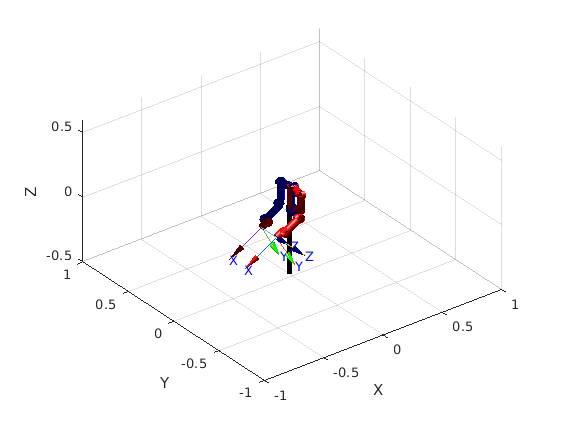

hold on
LeftArm.plot(Q, 'jointcolor', 'b', 'linkcolor', 'r', 'jointdiam', 0.5, ...
    'nojoints', 'workspace', [-1 1 -1 1 -1 1], ...
    'noname', 'noshadow');
    zlim([-1, 1]);

hold on
RightArm.plot(Q, 'jointcolor', 'r', 'linkcolor', 'b', 'jointdiam', 0.5,...
    'nojoints', 'workspace', [-1 1 -1 1 -1 1], ...
    'noname', 'noshadow', 'nobase');
    zlim([-0.5, 0.6]);

## Import Right Arm from forked iKin

Used to compare it with the CAD right arm

RightTableCode = readtable('fork_right_v2.5.csv');
RightTableCode.Properties.VariableNames = {'a', 'd', 'alpha', 'offset', 'min', 'max'};
RightArmCode = Revolute('d', RightTableCode.d(1), 'a', RightTableCode.a(1), 'alpha', deg2rad(RightTableCode.alpha(1)), 'offset', deg2rad(RightTableCode.offset(1)));
for i=2:height(RightTableCode)
   RightArmCode = RightArmCode + Revolute('d', RightTableCode.d(i), 'a', RightTableCode.a(i), 'alpha', deg2rad(RightTableCode.alpha(i)), 'offset', deg2rad(RightTableCode.offset(i)));
end
RightArmCode.name = 'Code';


homtable = readtable('resources/icubarm_right_urdf_h0_hn.txt');
h = zeros(4,4);
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{1, k};
        k = k+1;
    end
end
RightArmCode.base = h;
                
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{2, k};
        k = k+1;
    end
end
RightArmCode.tool = h;

## Plot Arms

hold on
RightArmCode.plot(Q, 'jointcolor', 'b', 'linkcolor', 'r', 'jointdiam', 0.5, ...
    'nojoints', 'workspace', [-1 1 -1 1 -1 1], ...
    'noshadow');
    zlim([-1, 1]);
alpha(0.5)
hold on
RightArm.plot(Q, 'jointcolor', 'r', 'linkcolor', 'b', 'jointdiam', 0.5,...
    'nojoints', 'workspace', [-1 1 -1 1 -1 1], ...
    'noshadow', 'nobase');
    zlim([-0.5, 0.6]);
alpha(0.1)